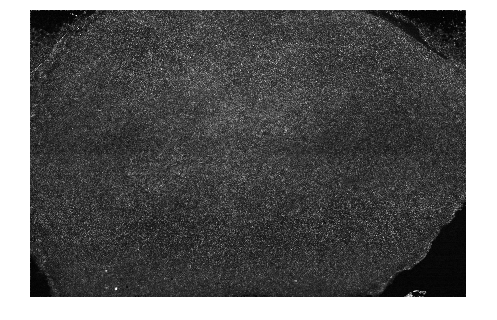

im_245=read(Tiff('\\lfs.lifesci.dundee.ac.uk\lfs\cjw\DSLM_expk\expk0245\0003_merge\merged_images\merge\img_0006.tif'));
imshow(im_245,[]);

DLSM_pixel=.65 ;%microns
confocal_pixel = 1/5.548 ;
confocal_tile = @(x) round(x*DLSM_pixel/confocal_pixel); %to get 
%equivalent tile size to 180, 256, etc pixel tiles on DLSM images

tile_size_DSLM=256;
tile_size_confocal=confocal_tile(tile_size_DSLM)

tile_size_confocal = 923

FT = @(x) abs(fftshift(fft2(perdecomp(x))));

loc1_DSLM = [6200, 2000] %cells right of streak

loc1_DSLM =         6200        2000


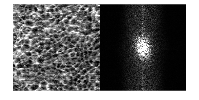

data=im_245(loc1_DSLM(2):loc1_DSLM(2)+tile_size_DSLM, loc1_DSLM(1):loc1_DSLM(1)+tile_size_DSLM);
FT_loc1_DSLM =FT(data);
montage({imadjust(data)./1,(FT_loc1_DSLM)./10000});

loc1_DSLM = [6200, 2000] %tried removing stripes

loc1_DSLM =         6200        2000


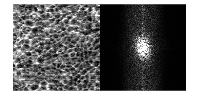

data2=im245_2(loc1_DSLM(2):loc1_DSLM(2)+tile_size_DSLM, loc1_DSLM(1):loc1_DSLM(1)+tile_size_DSLM);
data2=cast(data2,'uint8');
FT_loc1_DSLM2 =FT(data2);
montage({imadjust(data2)./1,(FT_loc1_DSLM2)./10000});

loc2_DSLM = [6800, 4300] %black lower right corner

loc2_DSLM =         6800        4300


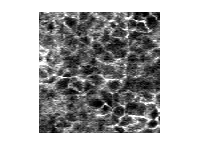

data2black=im_245(loc2_DSLM(2):loc2_DSLM(2)+tile_size_DSLM, loc2_DSLM(1):loc2_DSLM(1)+tile_size_DSLM);
imshow(imadjust(data2black),[]);

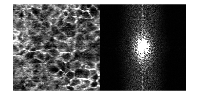

FT_loc2_DSLM =FT(data2black);
montage({imadjust(data2black)./1,(FT_loc2_DSLM)./10000});

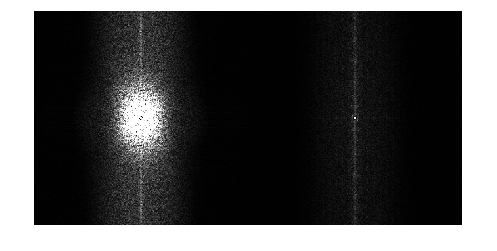

montage({(FT_loc1_DSLM)./10000,(FT_loc2_DSLM)./10000});

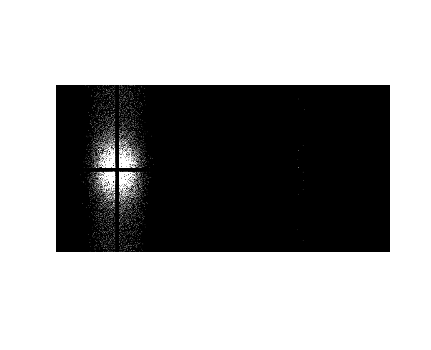

thr=2500;
montage({stripemask(FT_loc1_DSLM,thr)./10000,stripemask(FT_loc2_DSLM,thr)./10000});

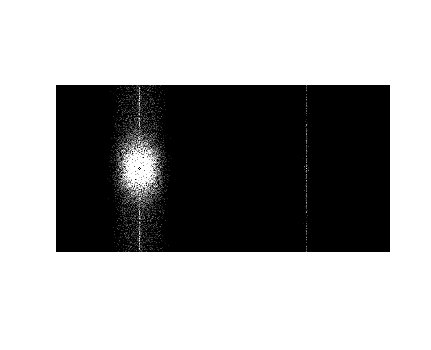

thr=2500;
montage({thresholdmask(FT_loc1_DSLM,thr)./10000,thresholdmask(FT_loc2_DSLM,thr)./10000});

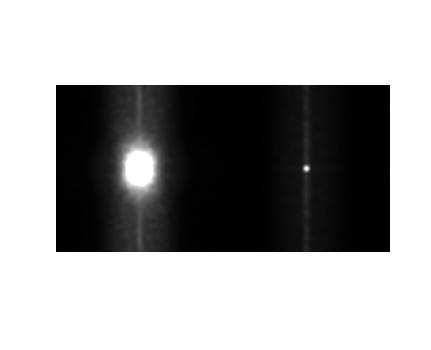

montage({imgaussfilt(FT_loc1_DSLM,3)./10000,imgaussfilt(FT_loc2_DSLM,3)./10000}, []);

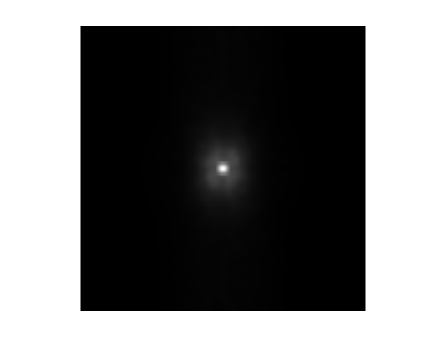

imshow((imgaussfilt(FT_loc1_DSLM,3)-imgaussfilt(FT_loc2_DSLM,3))./10000,[]);

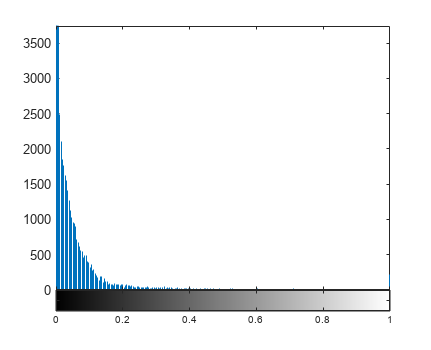

imhist(FT_loc1_DSLM/(.01*max(FT_loc1_DSLM, [], "all")));

imhist(FT_loc2_DSLM/(.01*max(FT_loc1_DSLM, [], "all")));

imhist(stripemask(FT_loc1_DSLM)./(max(FT_loc1_DSLM, [], "all")));
xlim([0, .1])
ylim([0,1500])

imhist(stripemask(FT_loc2_DSLM)./(max(FT_loc1_DSLM, [], "all")));

loc1 = [2700,850]; %in upper right uniform area
tile1a = im_confocal_a(loc1(2):loc1(2)+tile_size_confocal,loc1(1):loc1(1)+tile_size_confocal);
imshow(tile1a,[])
tile1m = im_confocal_m(loc1(2):loc1(2)+tile_size_confocal,loc1(1):loc1(1)+tile_size_confocal);
imshow(tile1m,[])

function im=stripemask(im, thr)
stripewidth=4;
dims=size(im);
Mask = zeros(dims(1), dims(2), "logical");
Mask(round((dims(1)-stripewidth)/2):round((dims(1)+stripewidth)/2),:) = true;
Mask(:,round((dims(2)-stripewidth)/2):round((dims(2)+stripewidth)/2)) = true;
%also filter out values below threshold
Mask = Mask | reshape(im<thr, dims(1), dims(2));
im(logical(Mask)) = 0;
end



function im=thresholdmask(im, thr)
dims=size(im);
Mask = zeros(dims(1), dims(2), "logical");
%also filter out values below threshold
Mask = Mask | reshape(im<thr, dims(1), dims(2));
im(logical(Mask)) = 0;
end

function im=stripemaskgausssian(im, thr)
stripewidth=4;
dims=size(im);
Mask = zeros(dims(1), dims(2), "logical");
Mask(round((dims(1)-stripewidth)/2):round((dims(1)+stripewidth)/2),:) = true;
Mask(:,round((dims(2)-stripewidth)/2):round((dims(2)+stripewidth)/2)) = true;
%also filter out values below threshold
Mask = Mask | reshape(im<thr, dims(1), dims(2));
im(logical(Mask)) = 0;
end